# Delay

## Test signals

addpath(genpath('Test Signals'));
[dirac, fs] = audioread('diracTest.wav');
[ess, fs] = audioread('sineSweep.wav');
[pink_noise, fs] = audioread('pinkNoise.wav');

## Dirac Delta

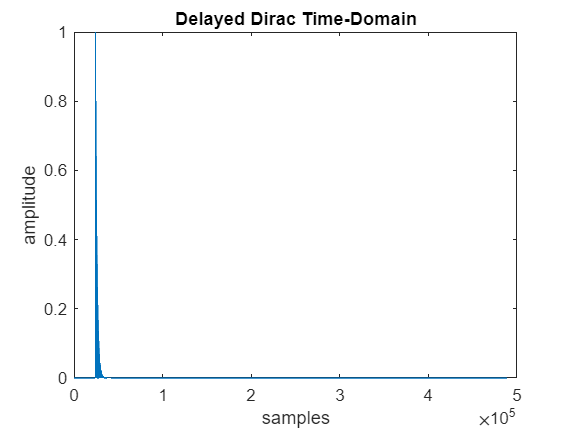

% set buffer parameters
buff_length = 480;

% set delay params
delayTime = 10;
fs = 44100;
fb = 0.8;

% initialize delay plugin
delay = Delay(delayTime, fs, fb, buff_length);

dirac_out = delay.process(dirac);

figure(1);
plot(dirac_out);
title('Delayed Dirac Time-Domain');
xlabel('samples');
ylabel('amplitude');

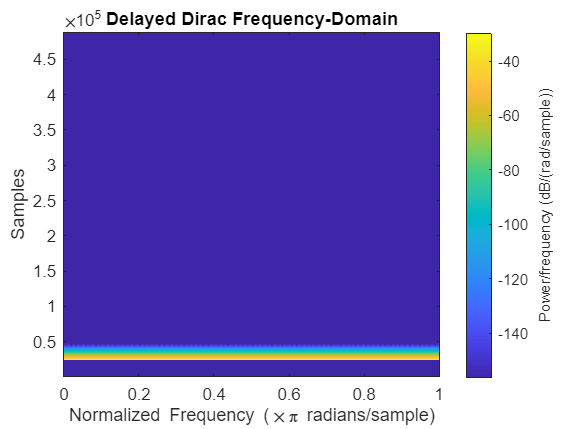



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(2);
spectrogram(dirac_out, hamming(win_length), overlap_length, nfft);
title('Delayed Dirac Frequency-Domain');

## ESS

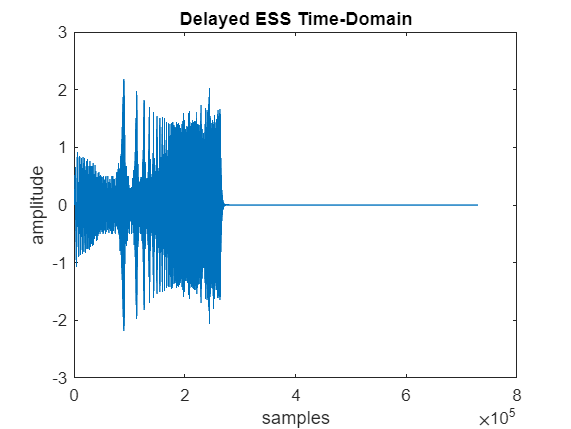

% use delay from above
% set variables for buffering and loop through test signal

ess_out = delay.process(ess);

figure(3);
plot(ess_out);
title('Delayed ESS Time-Domain');
xlabel('samples');
ylabel('amplitude');

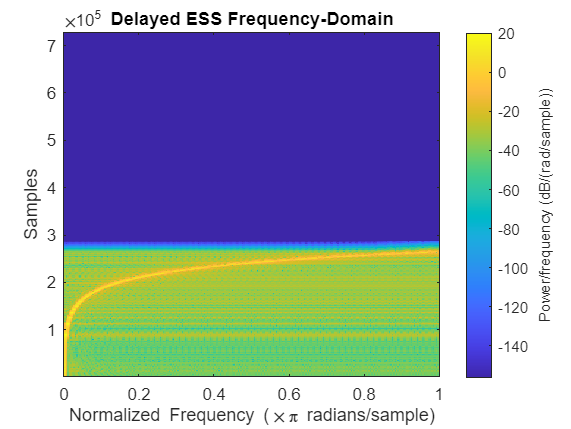



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(4);
spectrogram(ess_out, hamming(win_length), overlap_length, nfft);
title('Delayed ESS Frequency-Domain');

## Pink Noise

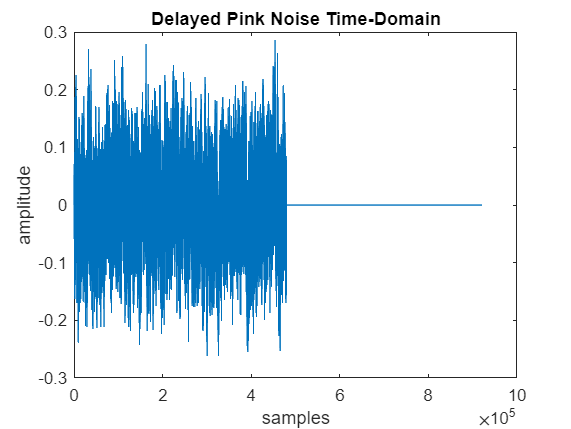

% use delay from above
% set variables for buffering and loop through test signal
pn_out = delay.process(pink_noise);

figure(5);
plot(pn_out);
title('Delayed Pink Noise Time-Domain');
xlabel('samples');
ylabel('amplitude');

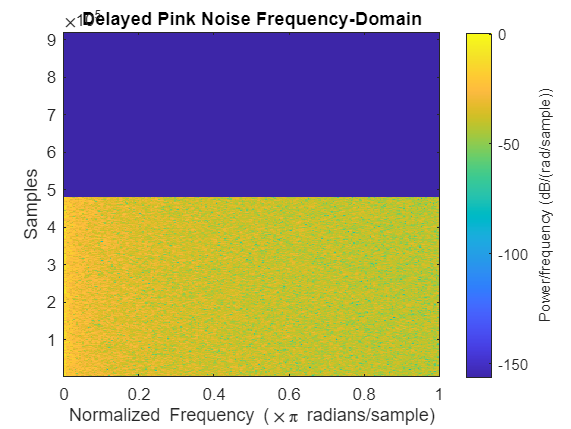



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(6);
spectrogram(pn_out, hamming(win_length), overlap_length, nfft);
title('Delayed Pink Noise Frequency-Domain');